clc; clear; close all;
%% Part c: Validate simple Y-axis rotation
disp("Validating Y-axis rotation...");

Validating Y-axis rotation...


beta_simple = deg2rad(90); % Example β = 20 degrees
P_B = [0; 0; 1]; % Original point in ^B frame

Ry_simple = [cos(beta_simple), 0, sin(beta_simple);
             0,                1, 0;
             -sin(beta_simple), 0, cos(beta_simple)];
P_A = Ry_simple * P_B; % Calculate rotated point
%这是旋转算子，绕固定坐标系Y轴，因此左乘
disp("Rotated Point (^A P):");

Rotated Point (^A P):


disp(P_A);

    1.0000
         0
    0.0000



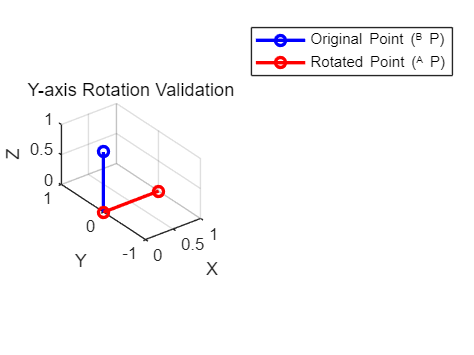


% Plot original and rotated points
figure;
plot3([0, P_B(1)], [0, P_B(2)], [0, P_B(3)], 'b-o', 'LineWidth', 2); hold on;
plot3([0, P_A(1)], [0, P_A(2)], [0, P_A(3)], 'r-o', 'LineWidth', 2);
legend('Original Point (^B P)', 'Rotated Point (^A P)');
xlabel('X'); ylabel('Y'); zlabel('Z');
grid on;
title('Y-axis Rotation Validation');
axis equal;